## Example #1

### 3D regular sampling + mesh

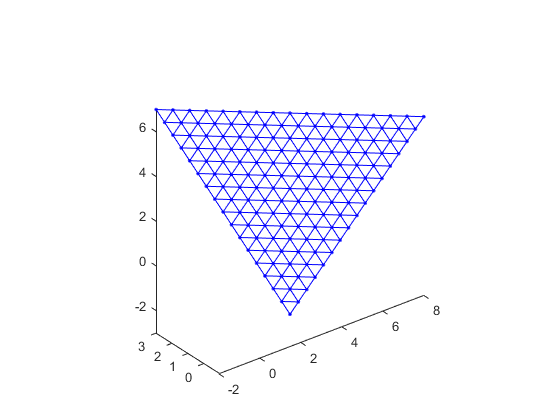

V1 = [-2 3 7]';
V2 = [8 -1 5]';
V3 = [3 1 -3]';
nstep = 16;
[V, T] = sample_triangle(V1, V2, V3, nstep);
TRI = triangulation(T, V(:,1), V(:,2), V(:,3));
figure;
plot3(V(:,1), V(:,2), V(:,3), 'b.', 'Linewidth', 2), hold on;
trimesh(TRI);
colormap([0 0 1]);
axis equal, axis tight;

## Example #2

### 4D example

### Random sampling and its 3D projection

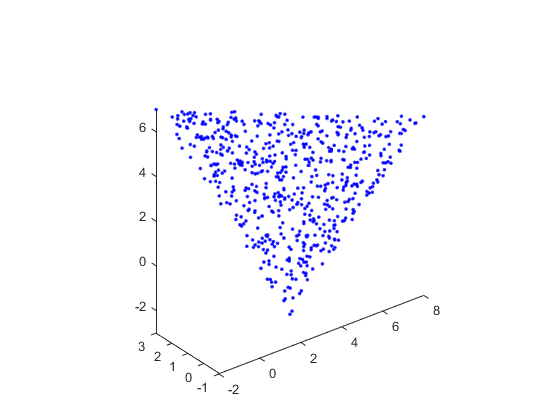

V1 = [-2 3 7 1]';
V2 = [8 -1 5 2]';
V3 = [3 1 -3 -2]';
nstep = 16;
option_random = true;
V = sample_triangle(V1, V2, V3, nstep, option_random, 600);
figure;
plot3(V(:,1), V(:,2), V(:,3), 'b.', 'Linewidth', 2), hold on;
axis equal, axis tight;